## Układ zamodelowany w Simulinku

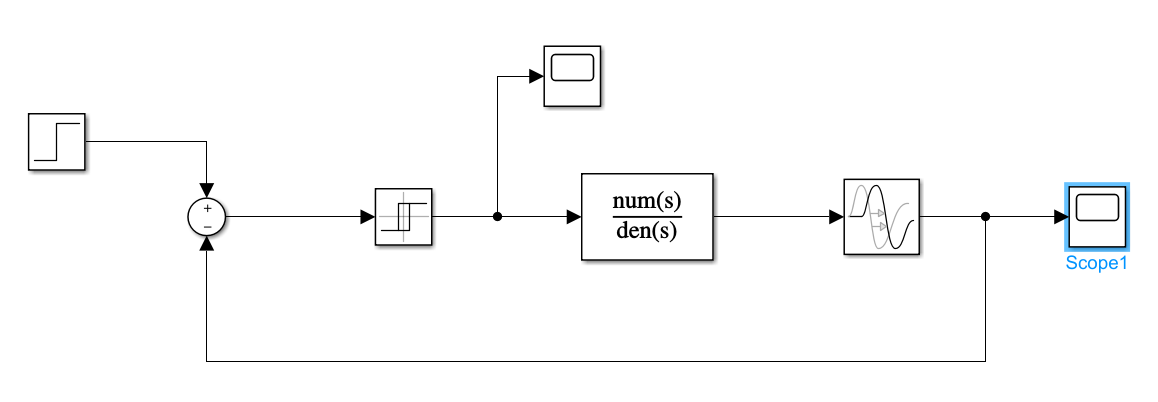

## Obiekt statyczny

Transmitancja obiektu:

Gdzie :

             $\tau \;$         - czas martwy

            T1         - stała czasowa obiektu 

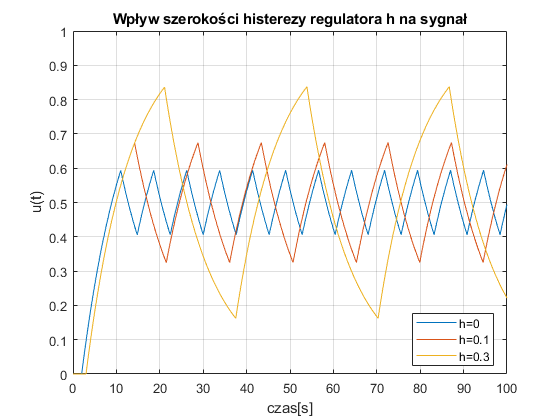

T = 10;
tau = 2;
SP = 0.5;


figure;
for h=[0 0.1 0.3]
    out = sim('Lab5');
    y = out.y;
    u = out.u;
    l = append("h=", string(h));
    plot(u.time,u.signals.values,'DisplayName',l)
    grid
    xlabel('czas[s]')
    ylabel('u(t)')
    axis([0,100,0,1])
    legend("Location","best");
    hold on
end
title("Wpływ szerokości histerezy regulatora h na sygnał")

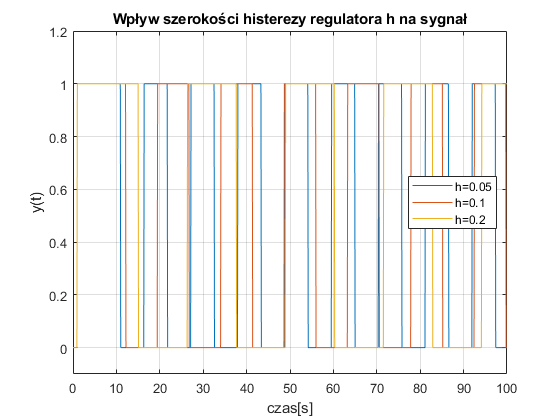


figure;
for h=[0.05 0.1 0.2]
    out = sim('Lab5');
    y = out.y;
    u = out.u;
    l = append("h=", string(h));
    plot(y.time,y.signals.values,'DisplayName',l)
    grid
    xlabel('czas[s]')
    ylabel('y(t)')
    axis([0,100,-0.1,1.2])
    legend("Location","best");
    hold on
end
title("Wpływ szerokości histerezy regulatora h na sygnał")

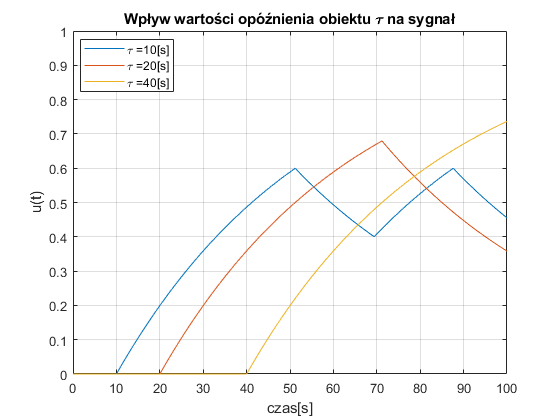

T = 45;
h = 0;
SP = 0.5;

figure;
for tau=[10 20 40]
    out = sim('Lab5');
    y = out.y;
    u = out.u;
    l = append("\tau =", string(tau),'[s]');
    plot(u.time,u.signals.values,'DisplayName',l)
    grid
    xlabel('czas[s]')
    ylabel('u(t)')
    axis([0,100,0,1])
    legend("Location","best");
    hold on
end
title("Wpływ wartości opóźnienia obiektu \tau na sygnał")

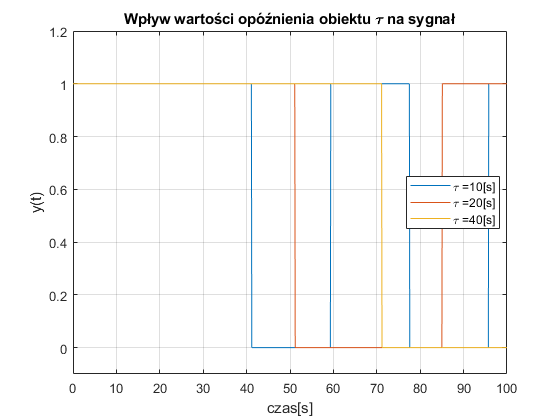


figure;
for tau=[10 20 40]
    out = sim('Lab5');
    y = out.y;
    u = out.u;
    l = append("\tau =", string(tau),'[s]');
    plot(y.time,y.signals.values,'DisplayName',l)
    grid
    xlabel('czas[s]')
    ylabel('y(t)')
    axis([0,100,-0.1,1.2])
    legend("Location","best");
    hold on
end
title("Wpływ wartości opóźnienia obiektu \tau na sygnał")

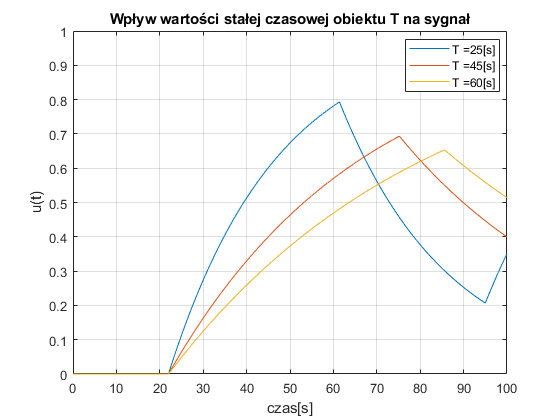

tau = 22;
h = 0;
SP = 0.5;

figure;
for T=[25 45 60]
    out = sim('Lab5');
    y = out.y;
    u = out.u;
    l = append("T =", string(T),'[s]');
    plot(u.time,u.signals.values,'DisplayName',l)
    grid
    xlabel('czas[s]')
    ylabel('u(t)')
    axis([0,100,0,1])
    legend("Location","best");
    hold on
end
title("Wpływ wartości stałej czasowej obiektu T na sygnał")

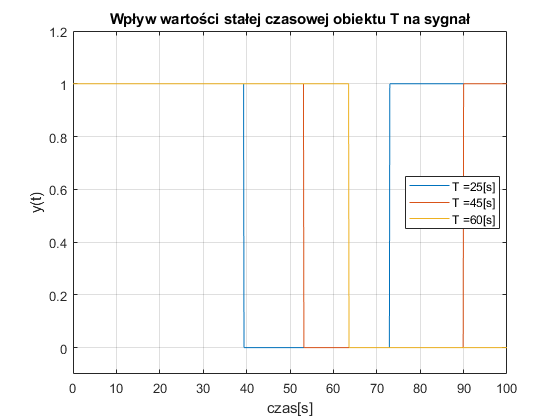


figure;
for T=[25 45 60]
    out = sim('Lab5');
    y = out.y;
    u = out.u;
    l = append("T =", string(T),'[s]');
    plot(y.time,y.signals.values,'DisplayName',l)
    grid
    xlabel('czas[s]')
    ylabel('y(t)')
    axis([0,100,-0.1,1.2])
    legend("Location","best");
    hold on
end
title("Wpływ wartości stałej czasowej obiektu T na sygnał")

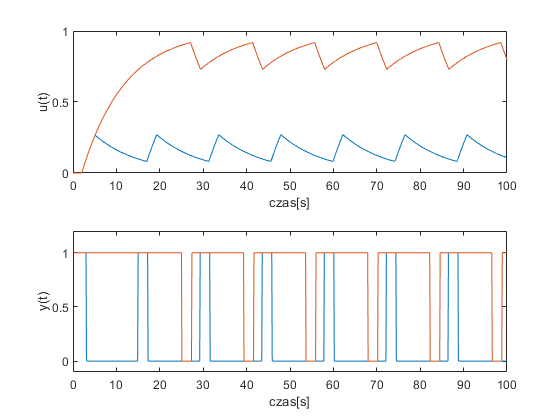

tau = 2;
h = 0;
T = 10;

figure
for SP=[0.1 0.9]
    subplot(2,1,1)
    out = sim('Lab5');
    y = out.y;
    u = out.u;
    plot(u.time,u.signals.values)
    grid
    xlabel('czas[s]')
    ylabel('u(t)')
    axis([0,100,0,1])
    hold on
end


for SP=[0.1 0.9]
    subplot(2,1,2)
    out = sim('Lab5');
    y = out.y;
    u = out.u;
    plot(y.time,y.signals.values)
    grid
    xlabel('czas[s]')
    ylabel('y(t)')
    axis([0,100,-0.1,1.2])
    hold on
end

## Obiekt astatyczny

Transmitancja obiektu:

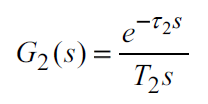

Gdzie :

             $\tau \;$         - czas martwy

            T2         - czas całkowania obiektu

tau = 22;
h = 0.1;
T = 45;

figure;
for SP=[0.2 0.5 1]
    subplot(2,1,1)
    out = sim('Lab5_astatyczny');
    y = out.y;
    u = out.u;
    plot(u.time,u.signals.values)
    grid
    xlabel('czas[s]')
    ylabel('u(t)')
    axis([0,300,-1,2])
    hold on
end

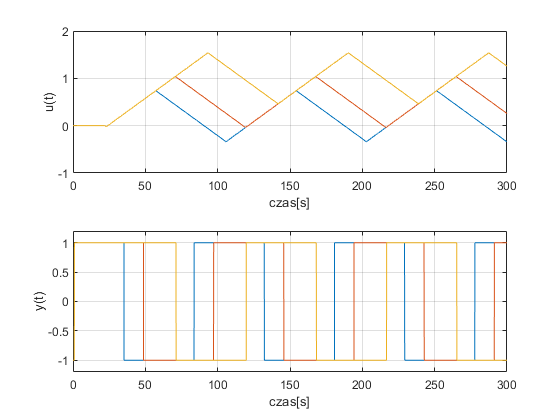



for SP=[0.2 0.5 1]
    subplot(2,1,2)
    out = sim('Lab5_astatyczny');
    y = out.y;
    u = out.u;
    plot(y.time,y.signals.values)
    grid
    xlabel('czas[s]')
    ylabel('y(t)')
    axis([0,300,-1.2,1.2])
    hold on
end